# 0. 解析数据

clear
clc
 
ulogOBJ = ulogreader("07_03_18.ulg");
msg = readTopicMsgs(ulogOBJ);

# 1. 旋转轴估计与主轴估计

## 确定unknown_logger的序号，提取log数据

更换log文件后需要修改下面的数值，找到msg中对应的unknown_logger的序号是多少。

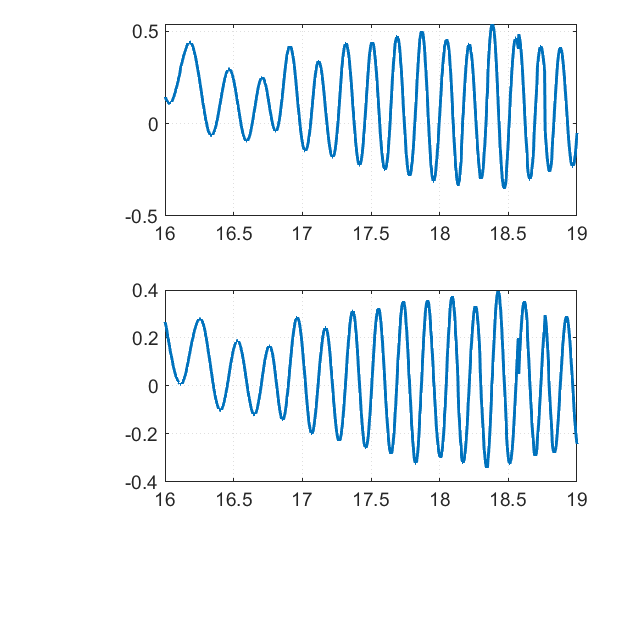

 
% 获取unknown_logger数据
logSampleRate = 250;
vehicle_attitude = msg.TopicMessages{17};
% 生成相对时间
log_time = vehicle_attitude.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 得到yaw为0的(无旋转的)旋转矩阵,并根据此得出机体旋转轴,相对的也可以理解为是地球坐标系的向量投射到机体系(无旋转)
% 左前方旋翼失效,俯仰角应该小于0, 横滚角应该大于0, 然而,根据RflySim3D显示和数显表明, 此时的横滚俯仰角均大于0!
quate = vehicle_attitude.q;
quate(:,1) = quate(:,1);
[vehicle_attitude_psi, pitch, roll] = quat2angle(quate);%该矩阵可以将地球坐标系下的向量投射到机体坐标系,反之是将向量旋转-roll和-pitch
% 计算倾斜矩阵(无旋转)(e-->b)
yaw = zeros(sample_count,1);
angle = angle2dcm(yaw,pitch,roll);

% 利用倾斜矩阵计算旋转轴
rotation_axis = zeros(sample_count,3);
for i=1:sample_count
    rotation_axis(i,:) = angle(:,:,i)*[0,0,1]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2.5,'SampleRate',250);
rotation_axis_xf = filtfilt(d,double(rotation_axis(:,1)));
rotation_axis_yf = filtfilt(d,double(rotation_axis(:,2)));
rotation_axis_zf = filtfilt(d,double(rotation_axis(:,3)));

%% 绘制欧拉角的图
s = figure(11);
clf
subplot(2,1,1)
plot(relativeTime,roll)
xlim([16, 19])

subplot(2,1,2)
plot(relativeTime,pitch)
xlim([16, 19])

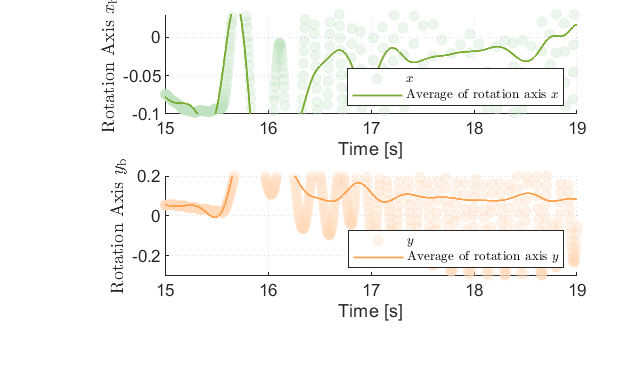

%% 绘图主轴估计图
s = figure(12);
s.Position(4) = 8.0;
clf
subplot(2,1,1)
% area(relativeTime,rotation_axis(:,1),'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,'BaseValue',-0.02)
scatter(relativeTime,rotation_axis(:,1),'MarkerEdgeColor','#c0e2c0','MarkerFaceColor',"#c0e2c0",'MarkerEdgeAlpha',.3,'MarkerFaceAlpha',.3)
hold on
plot(relativeTime,rotation_axis_xf,'LineWidth',1,'Color','#77AC30')
xlim([15, 19])
ylim([-0.1 0.03])
xlabel("Time [s]")
ylabel("Rotation Axis $x_{\mathrm{b}}$","Interpreter","latex")
legend('$x$','Average of rotation axis $x$',"Interpreter","latex",'Location',"best")
legend('Box',"on",'FontSize',8)

subplot(2,1,2)
% area(relativeTime,rotation_axis(:,2),'FaceColor','#ffd8b7','EdgeColor','#ffd8b7','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,"BaseValue",0.1)
scatter(relativeTime,rotation_axis(:,2),'MarkerEdgeColor','#ffd8b7','MarkerFaceColor','#ffd8b7','MarkerEdgeAlpha',.3,'MarkerFaceAlpha',.3)
hold on
plot(relativeTime,rotation_axis_yf,'LineWidth',1,'Color','#ffa04d')
xlim([15, 19])
ylim([-0.3 0.2])
xlabel("Time [s]")
ylabel("Rotation Axis $y_{\mathrm{b}}$","Interpreter","latex")
legend('$y$','Average of rotation axis $y$',"Interpreter","latex",'Location',"best")
legend('Box',"on",'FontSize',8)

## 1.2 计算主轴曲线

% 获取方位角速度
yawspeed = vehicle_attitude.yawspeed;
% 获取旋转矩阵e-->b
angle_be = quat2dcm(quate);
% 计算主轴(机体Z轴到地球坐标系下的坐标described in the Earth Frame)
primary_axis = zeros(sample_count,3);
for i=1:sample_count
    primary_axis(i,:) = angle_be(:,:,i)'*[0,0,1]';
end
% 画图
figure(13)
clf
subplot(3,1,1)
plot(relativeTime, primary_axis)
xlim([15, 19])
ylabel("$\mathbf{n}_3$","Interpreter","latex")
legend("$n_{3,x}$","$n_{3,y}$","$n_{3,z}$","Interpreter","latex")

# 2. 角速率

 
% 获取unknown_logger数据
logSampleRate = 250;
sensor_combined = msg.TopicMessages{12};
% 生成相对时间
log_time = sensor_combined.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% sensor_combined
gyro = sensor_combined.gyro_rad;
% 接着figure(13)画图
figure(13)
subplot(3,1,2)
plot(relativeTime, gyro)
xlim([15, 19])
% xlabel("Time [s]")
ylabel("Body Angular Velocity")
ylabel("$\mathbf{\omega}$ [rad/s]",'Interpreter',"latex")
legend("$p$","$q$","$r$","Interpreter","latex")

# 3. PWM对比

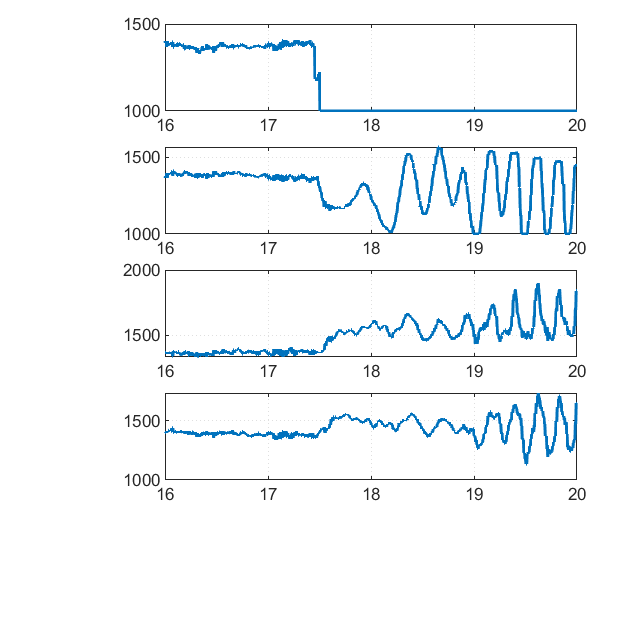

% 获取unknown_logger数据
logSampleRate = 250;
actuator_outputs = msg.TopicMessages{1};
% 生成相对时间
log_time = actuator_outputs.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% actuator_outputs
PWM8 = (actuator_outputs.output);
PWM4 = PWM8(:,1:4);
PWM4(1,:) = [0,0,0,0];
for i=2:1:sample_count
    for k = 1:4
        if PWM4(i,k) == 1500
            PWM4(i,k) = PWM4(i-1,k);
        end
    end
end
figure(31)
clf
subplot(4,1,1)
plot(relativeTime, PWM4(:,1))
xlim([16, 20])

subplot(4,1,2)
plot(relativeTime, PWM4(:,2))
xlim([16, 20])

subplot(4,1,3)
plot(relativeTime, PWM4(:,3))
xlim([16, 20])

subplot(4,1,4)
plot(relativeTime, PWM4(:,4))
xlim([16, 20])

# 4. 遥控通道

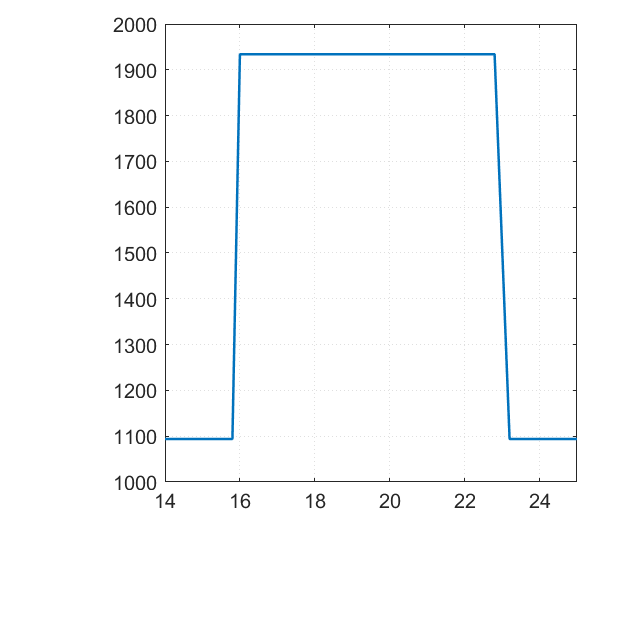

% 获取unknown_logger数据
logSampleRate = 5;
input_rc = msg.TopicMessages{8};
% 生成相对时间
log_time = input_rc.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
rc = input_rc.values;
ch6 = rc(:,6);
figure(41)
clf
plot(relativeTime, ch6)
xlim([14, 25])

# 5. 位置

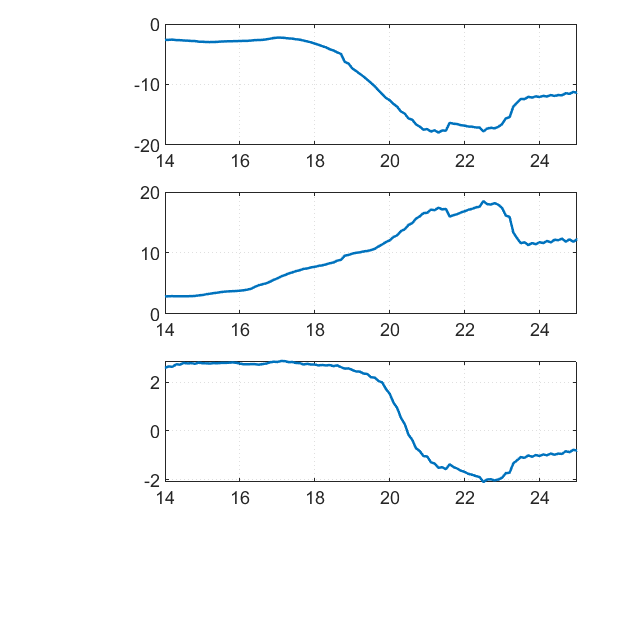

% 获取unknown_logger数据
logSampleRate = 10;
vehicle_local_position = msg.TopicMessages{22};
% 生成相对时间
log_time = vehicle_local_position.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
local_position_x = vehicle_local_position.x;
local_position_y = vehicle_local_position.y;
local_position_z = vehicle_local_position.z;

% 
figure(51)
subplot(3,1,1)
plot(relativeTime, local_position_x)
xlim([14, 25])

subplot(3,1,2)
plot(relativeTime, local_position_y)
xlim([14, 25])

subplot(3,1,3)
plot(relativeTime, -local_position_z)
xlim([14, 25])

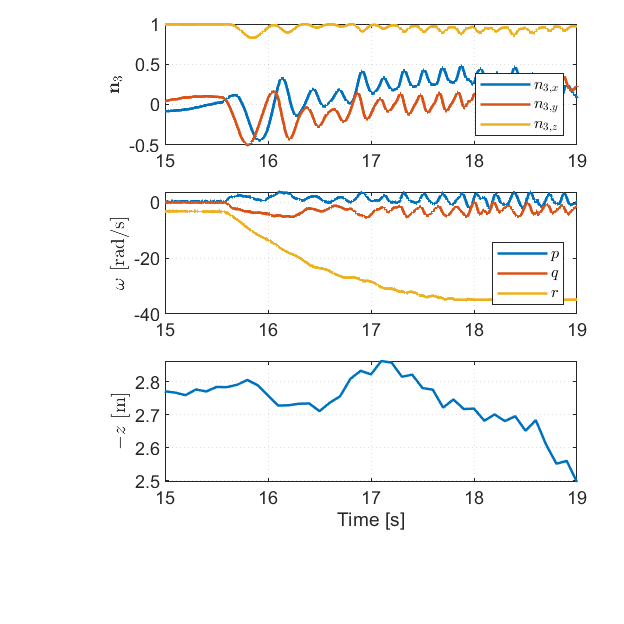

figure(13)
subplot(3,1,3)
plot(relativeTime, -local_position_z)
xlim([15, 19])
xlabel("Time [s]")
ylabel("$-z$ [m]",'Interpreter',"latex")

% legend("$p$","Interpreter","latex")